clc; close all; clear all; warning off;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% d_prime_s_res=0.2;  %% maximum distance resolution, m
% 
% tau_s_0=[0.0001,0.001,0.002,0.003,0.004,0.005,0.008,0.01,0.015,0.02]; %%  threshold in sensing

r_c_com_0=[0.5e9];  %% threshold/required data rate in communication

gamma_bs_0= [10:10:300]/1000^2;  %%  density of base station, point/m^2

gamma_sct= 300/1000^2; %% density of SCT, point/m^2

gamma_st= 300/1000^2;   %% density of ST, point/m^2

eta=0.5;  %% first \beta part of the spectrum is allocated to sensing

mu=0.5;  %%  first \mu part of the power is allocated to sensing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('parameters.mlx');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ana_P_c_cov_2=zeros(size(r_c_com_0,2),size(gamma_bs_0,2));
Sim_P_c_cov_2=zeros(size(r_c_com_0,2),size(gamma_bs_0,2));

for tt=1:size(r_c_com_0,2)
    
    tau_c=2^(r_c_com_0(1,tt)/B_c/1e6)-1;
    
    for gg=1:size(gamma_bs_0,2)
        gamma_bs=gamma_bs_0(1,gg)
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        int_c1=@(r_bt) exp(-tau_c    *N_0*B_c*1e6      *f_c^2*r_bt^1.9/P_ct/g_cb*10^(0.1*(L_gr+L_ai)-2.8)); %% B_c is with the unit of MHz
        
        int_c2=@(r_bt) integral( @(r_bjt)  tau_c/(tau_c+(r_bjt/r_bt)^1.9)*r_bjt, r_bt, r_bjt_max,"ArrayValued",true);
        
        A_cj=@(r_bjtj) atan(C_d/2/r_bjtj)/pi;
        
        f_r_bjtj=@(r_bjtj) 2*pi*gamma_sct*r_bjtj*exp(-pi*gamma_sct*r_bjtj^2);
        
        int_c3=@(r_bt)  integral( @(r_bjtj)  exp(-2*pi*gamma_bs*A_cj(r_bjtj)* int_c2(r_bt))* f_r_bjtj(r_bjtj) , 0, r_bjtj_max, "ArrayValued",true );
        
        Ana_P_c_cov_2(tt,gg)=  integral(@(r_bt)  int_c1(r_bt)* int_c3(r_bt)*  2*pi*gamma_bs*r_bt*exp(-pi*gamma_bs*r_bt^2), 0, r_bt_max, "ArrayValued",true );
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        iteration=100000;
        
        SINR_c=zeros(1,iteration);
        parfor ii=1:iteration
            
           [BS_xy_R_sort,R_bt,R_bjt,SCT_j_xy,theta_j] = make_BS_SCT(range_xy_BS,range_xy_SCT,gamma_bs,gamma_sct,C_d,r_bt_max,r_bjt_max,r_bjtj_max);
           
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            
            P_cr_Rbt=P_ct*10^2.8/f_c^2/R_bt^1.9/10^(0.1*(L_gr+L_ai))*exprnd(1)*g_cb;
            
            I_c= P_ct*10^2.8/f_c^2./R_bjt.^1.9/10^(0.1*(L_gr+L_ai))*exprnd(1)*g_cb .*theta_j'/2/pi ;
            I_c=sum(I_c);
            
            SINR_c(1,ii)=P_cr_Rbt/(N_0*B_c*1e6+I_c);  %% B_c is with the unit of MHz
            
        end
        Sim_P_c_cov_2(tt,gg)=sum(SINR_c >= tau_c)/iteration;
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
end

gamma_bs = 1.0000e-05

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 20).


gamma_bs = 2.0000e-05

gamma_bs = 3.0000e-05

gamma_bs = 4.0000e-05

gamma_bs = 5.0000e-05

gamma_bs = 6.0000e-05

gamma_bs = 7.0000e-05

gamma_bs = 8.0000e-05

gamma_bs = 9.0000e-05

gamma_bs = 1.0000e-04

gamma_bs = 1.1000e-04

gamma_bs = 1.2000e-04

gamma_bs = 1.3000e-04

gamma_bs = 1.4000e-04

gamma_bs = 1.5000e-04

gamma_bs = 1.6000e-04

gamma_bs = 1.7000e-04

gamma_bs = 1.8000e-04

gamma_bs = 1.9000e-04

gamma_bs = 2.0000e-04

gamma_bs = 2.1000e-04

gamma_bs = 2.2000e-04

gamma_bs = 2.3000e-04

gamma_bs = 2.4000e-04

gamma_bs = 2.5000e-04

gamma_bs = 2.6000e-04

gamma_bs = 2.7000e-04

gamma_bs = 2.8000e-04

gamma_bs = 2.9000e-04

gamma_bs = 3.0000e-04

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
save('data/Ana_P_c_cov_2.mat','Ana_P_c_cov_2');
save('data/Sim_P_c_cov_2.mat','Sim_P_c_cov_2');



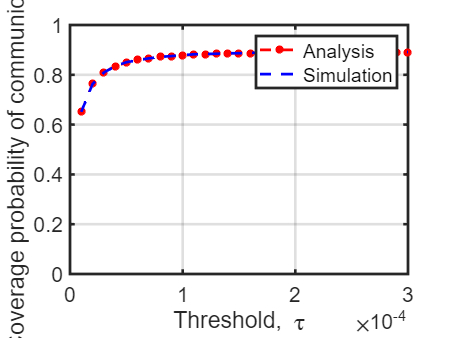



for tt=1:size(r_c_com_0,2)
    figure();
    plot(gamma_bs_0, Ana_P_c_cov_2(tt,:),'--*r','LineWidth',2);hold on;
    plot(gamma_bs_0, Sim_P_c_cov_2(tt,:),'--b','LineWidth',2);hold on;
    
    legend('Analysis','Simulation');
    xlabel('Threshold, \tau');
    ylabel('Coverage probability of communictaion' );
    ylim([0,1]);
    set(gca,'LineWidth',2,'FontSize',16);
    grid on;
    hold off;
end